clc;
clear;
close all;

%Record voice
fs = 44100;        % Sampling frequency
recObj = audiorecorder(fs, 16, 1);  % 16-bit, mono

disp('Start speaking...')

Start speaking...


recordblocking(recObj, 2);  % Record for 2 seconds
disp('Recording finished.');

Recording finished.


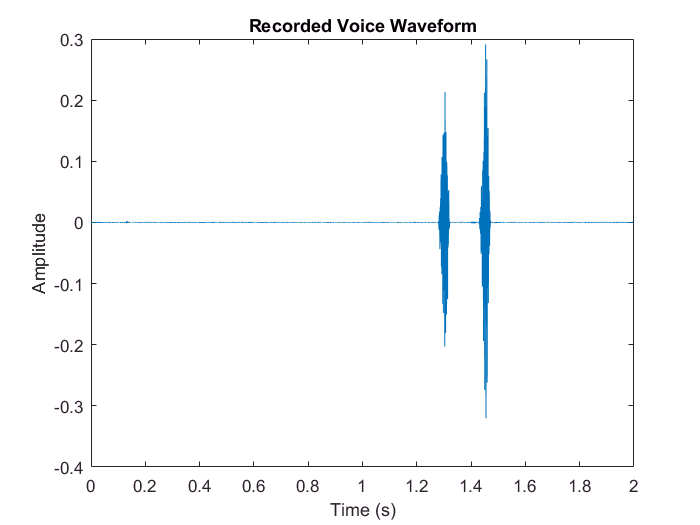


% Get recorded audio data
y = getaudiodata(recObj);

%% Plot waveform
t = (0:length(y)-1)/fs;
figure;
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Recorded Voice Waveform');


%% Pitch Detection using Autocorrelation
y = y - mean(y);    % Remove DC offset
N = length(y);

% Autocorrelation
[acor, lag] = xcorr(y);
acor = acor(lag >= 0);
lag = lag(lag >= 0);

% Ignore small lags (below 50 Hz) to remove noise
minLag = floor(fs/500); % ~500 Hz max pitch
maxLag = floor(fs/50);  % ~50 Hz min pitch

[~, I] = max(acor(minLag:maxLag));
I = I + minLag - 1;

pitchFreq = fs / I;

%% Gender Decision
if pitchFreq < 165
    gender = 'Male';
elseif pitchFreq >= 165 && pitchFreq <= 255
    gender = 'Female';
else
    gender = 'Unknown / High pitch';
end

% Display result
fprintf('Estimated Pitch Frequency: %.2f Hz\n', pitchFreq);

Estimated Pitch Frequency: 221.61 Hz


fprintf('Predicted Gender: %s\n', gender);

Predicted Gender: Female


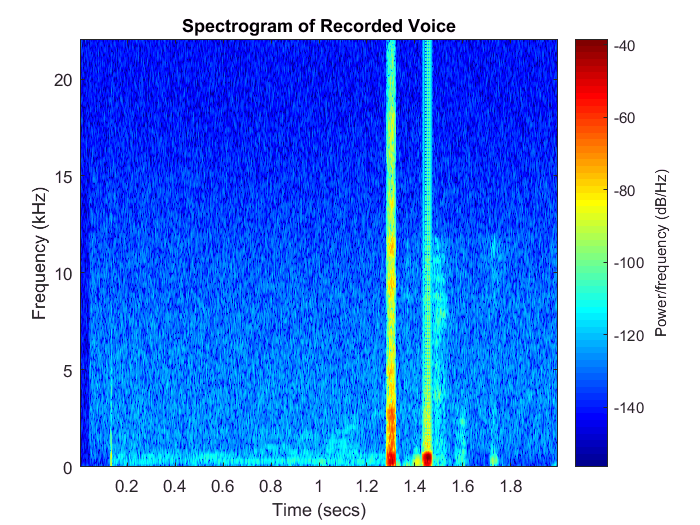


% Show Spectrogram for explanation
figure;
spectrogram(y, 256, 200, 1024, fs, 'yaxis');
title('Spectrogram of Recorded Voice');
colormap jet;